# 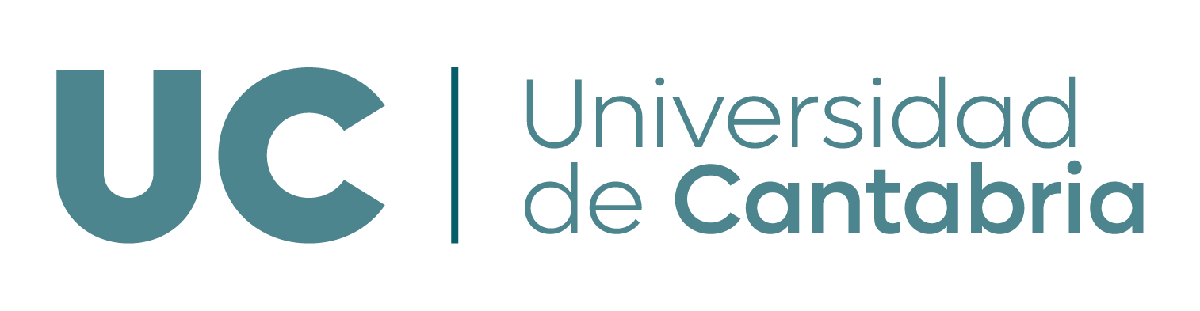

# **Estadística Descriptiva con MATLAB**

Asignatura: Métodos Matemáticos en la Ingeniería.

Profesoras: Vera Egorova y Sara Pérez Carabaza, Universidad de Cantabria. 

Guión basado en los guiones para Octave realizados por Jesús Fernandez y María Dolores Frías (Universidad de Cantabria).

### Indice de contenidos

La métodos de estadística descriptiva permiten resumir la información de un conjunto de datos mediante tablas de frecuencia, estadísticos y representaciones gráficas.

1.Lectura de datos

2. Tablas de frecuencia

  2.1 Ejercicio propuesto 1: tabla de frecuencias

3.Estadísticos 

   3.1 Ejercicio propuesto 2: help funcion mode

   3.1 Ejercicio propuesto 3: función coeficiente asimetría. 

4. Gráficos

5. Análisis factorizado

  5.1 Ejercicio propuesto 4: análisis factorizado 

clear all
close all

### 1. Lectura de datos

Una primera forma de tener una muestra de datos cargada en un vector en Matlab es introducirla directamente. Podemos definir un vector fila indicando los elementos separados por comas o por espacios.

datos = [10.8 11.9 12.7 9.2 13.2 8 13.8 8.4]

datos =    10.8000   11.9000   12.7000    9.2000   13.2000    8.0000   13.8000    8.4000


En la práctica, esta forma de cargar datos sólo se utiliza en el caso, poco habitual, de tener una muestra muy pequeña. La toma de datos no suele estar ligada al lenguaje de programación con el que se va a analizar después, así que es mucho más común recoger los datos en un fichero independiente. Por ejemplo, un fichero de texto plano. Si este fichero es suficientemente sencillo, lo podemos leer directamente con la función ***load****.* Por ejemplo, si en el block de notas o en el editor de Matlab creamos un fichero datos.txt con este contenido:

datos = load('datos.txt');

Obviamente, para que esta instrucción funcione, debemos pasarle la ruta completa hasta el fichero, o bien que éste se encuentre en el directorio de trabajo.

 Esta función también permite cargar una matriz de datos si el fichero de texto tiene varias filas como esta (o un vector columna si los datos están dispuestos verticalmente). Tal y como nos indica la ayuda:

* S = load(FILENAME) loads the variables from a MAT-file into a structure array, or data from an ASCII file into a double-precision array. *

matriz = load('matriz.txt')

matriz =     30    10     6    80
    90     2     3     4
     2     4     4     5


Sin embargo si intentamos utilizar load con archivos más complejos que combinan datos numericos con datos categoricos, o que tengan algún cabecero informativo, otro separador decimal, o que estén separados unos de otros por caracteres que no sean espacios o comas, deberemos utilizar otras funciones más específicas para leer ficheros de texto.  En estos casos load nos dará error.

%pulsaciones = load('Pulsaciones.txt') ! error

Para ficheros más generales deberemos utilizar otras funciones más específicas para leer ficheros de texto. Los archivos de texto suelen contener una combinación de datos numéricos y de texto, así como nombres de variables y filas. Por ejemplo, como el archivo Pulsaciones.txt que comienza asi:

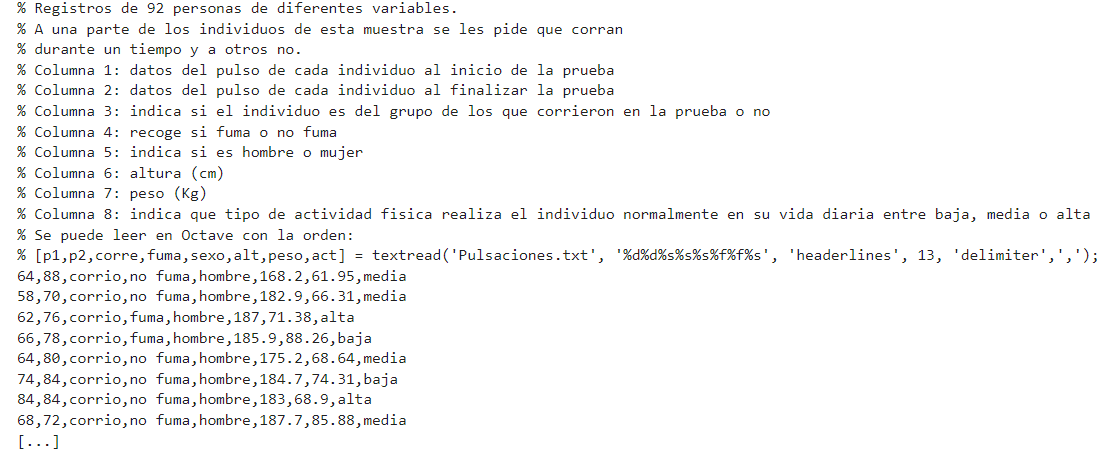

La primera fila contiene un encabezado que da nombre a cada una de las variables de cada registro. Cada fila representa un registro o individuo y cada columna distintos campos o variables sobre cada registro. Por tanto el fichero puede contener distintos tipos de datos (enteros, floats..) pero el tipo de dato de los valores de cada columna es el mismo.   

La función ***textread*** nos permite leer un documento de texto o (csv) y guardar cada variable (columna) en una variable independiente. Debemos indicarle el tipo de dato de cada columna del archivo que queremos leer. [help textread function](https://es.mathworks.com/help/matlab/ref/textread.html). Además especificamos los siguientes parámetros 'headerlines'=13 (número de lineas del encabezado) y 'delimiter'=',' ya que los datos del fichero están separados por comas.

%[A,B,C,...] = textread(filename,format).:  write to multiple outputs
% format: %d signed integer, %f float value, % s text
% parameters: delimiter (default none), headerlines (Ignores the specified number of lines at the beginning of the file.)..
[p1,p2,corre,fuma,sexo,alt,peso,act] = textread('Pulsaciones.txt', '%d%d%s%s%s%f%f%s', 'headerlines', 13, 'delimiter',',');

Se leen como columnas. Aquí lo podemos trasponer para visualizarlo mas cómodamente. Muchas de las funciones que veremos mas adelante funcionan indistintamente sobre vectores fila o columna.

p1=p1'

p1 =     64    58    62    66    64    74    84    68    62    76    90    80    92    68    60    62    66    70    68    72    70    74    66    70    96    62    78    82   100    68    96    78    88    62    80    62    60    72    62    76    68    54    74    74    68    72    68    82    64    58


Para determinar el número total de datos podemos utilizar la función ***length*** (número de elementos de un vector) 

%tamaño de la muestra
n=length(act)

n = 92

### **2.Tablas de frecuencias**

Para v**ariables cualitativas, semicuantitativas, o cuantitativas discretas** con pocos valores, podemos usar `unique` para encontrar los posibles valores que toma la variable, e `hist` para contar el número de veces (la frecuencia absoluta) que aparece cada uno en la muestra.

La función `hist` tiene varias opciones de formato:

- primer argumento de entrada: datos

- segundo argumento de entrada (opcional): número de intervalos para el histograma o vector con las marcas de clase de los intervalos. Sino se especifica el segundo argumento de entrada *hist* agrupará los datos en clases directamente.

argumentos de salida: 

- primer argumento (opcional): frecuencias absolutas

- segundo argumento (opcional): marcas de clase. 

Sino especificamos argumentos de salida hist dibujará un histograma.

A continuación se muestra el cálculo de las **frecuencias absolutas** de la **variable semicuantitativa actividad**.

%C=unique(A) devuelve los valores de A sin repeticiones  
%[C,ia,ic] = unique(A); tal que  C=A(ia)  A=C(ic)   
[xi, ~, ic] = unique(act); % xi(ic) reconstruiria la celda original (act)
ni= hist(ic, length(xi))

ni =     22     9    61


%podemos comprobar que el calculo de frecuencias absolutas es correcto: 
sum(strcmp(act,'baja'))

ans = 9

Procedemos de manera similar para el cálculo de las frecuencias absolutas y relativas de la variable cualitativa sexo

[xi, ~, ic] = unique(sexo); % xi(ic) reconstruiria la celda original (act)
ni= hist(ic, length(xi))

ni =     57    35


xi'

ans = 1×2 cell array
    {'hombre'}    {'mujer'}


ni

ni =     57    35


Nótese que para variables cualitativas como *Sexo* no tiene sentido el cálculo de frecuencias acumuladas, al no presentar este tipo de variables un orden. 

**Tratamiento individual. **En el caso de querer obtener  la frecuencia absoluta de una **variable cuantitativa discreta **(p. ej. la variable *p1*) también podemos utilizar la función *hist* para obtener las frecuencias absolutas. Si queremos una tabla de frecuencias de tratamiento individual deberemos especificar tantos intervalos como valores posibles toma p1. Pasamos un vector que defina las marcas de clase como los valores posibles que toma p1.

[xi, ~, ic] = unique(p1);%xi contiene los valores únicos de p1
ni=hist(ic,length(xi));
[xi' ni']

ans =     48     1
    54     2
    58     3
    60     4
    61     1
    62     9
    64     4
    66     5
    68    11
    70     6


Una vez obtenidas las frecuencias absolutas de la tabla, podemos calcular el resto de columnas de la tabla. Para la obtención de frecuencias acumuladas utilizamos la función `cumsum`***.***

fi=ni/n;%frecuencia relativa
Ni=cumsum(ni);%frecuencia absoluta acumulada
Fi=Ni/n;%frecuencia relativa acumulada
[xi' ni' fi' Ni' Fi']

ans =    48.0000    1.0000    0.0109    1.0000    0.0109
   54.0000    2.0000    0.0217    3.0000    0.0326
   58.0000    3.0000    0.0326    6.0000    0.0652
   60.0000    4.0000    0.0435   10.0000    0.1087
   61.0000    1.0000    0.0109   11.0000    0.1196
   62.0000    9.0000    0.0978   20.0000    0.2174
   64.0000    4.0000    0.0435   24.0000    0.2609
   66.0000    5.0000    0.0543   29.0000    0.3152
   68.0000   11.0000    0.1196   40.0000    0.4348
   70.0000    6.0000    0.0652   46.0000    0.5000


**Tratamiento de clase. **En el caso de quere obtener las** frecuencia absolutas **de **variables cuantitativas continuas **(p. ej. la variable *peso*) *hist* nos devuelve la frecuencia absoluta de cada clase, y la marca de clase.

[ni xi] = hist(peso);%obtenemos las frecuencias absolutas y las marcas de clase
%tabla de frecuencias absolutas
[xi' ni']

ans =    45.1730    2.0000
   50.6590   10.0000
   56.1450   15.0000
   61.6310   15.0000
   67.1170   22.0000
   72.6030   11.0000
   78.0890    6.0000
   83.5750    7.0000
   89.0610    3.0000
   94.5470    1.0000


¿Cuántas clases se ha considerado la función *hist* por defecto para la variable peso?

Podemos obtener las frecuencias absolutas para el número de clases que recomienda el criterio de Sturges.

sturges = @(x) floor(1+log10(n)/log10(2)); %funcion de tipo anónimo
c = sturges(n)

c = 8

[ni xi] = hist(peso, c);
num2str([xi' ni'])

ans = 8×20 char array
    '45.8588            4'
    '52.7163           16'
    '59.5738           19'
    '66.4313           25'
    '73.2887           13'
    '80.1463            9'
    '87.0037            5'
    '93.8613            1'


O bien, podemos especificar nosotros las marcas de clase, para elegir unos valores más redondos. 

%repetimos especificando directamente las marcas de clase
xi = 45:10:95;
ni = hist(peso, xi);
[xi' ni']

ans =     45     5
    55    24
    65    35
    75    17
    85    10
    95     1


Una vez obtenidas las frecuencias absolutas de la tabla, podemos calcular el resto de columnas de la tabla. Para la obtención de frecuencias acumuladas utilizamos la función ***cumsum.***

fi=ni/n;%frecuencia relativa
Ni=cumsum(ni);%frecuencia absoluta acumulada
Fi=cumsum(fi);%frecuencia relativa acumulada

Para mostrar la tabla mostramos una matriz donde cada frecuencia calculada se muestra en una columna. 

format short
tabla=[xi' ni' fi' Ni' Fi']

tabla =    45.0000    5.0000    0.0543    5.0000    0.0543
   55.0000   24.0000    0.2609   29.0000    0.3152
   65.0000   35.0000    0.3804   64.0000    0.6957
   75.0000   17.0000    0.1848   81.0000    0.8804
   85.0000   10.0000    0.1087   91.0000    0.9891
   95.0000    1.0000    0.0109   92.0000    1.0000


Podemos especificar mediante [format](https://es.mathworks.com/help/matlab/ref/format.html?searchHighlight=format&s_tid=srchtitle_format_1) un tipo de formato con el que se muestran los números en Matlab para que sea mas compacto y la tabla se vea mejor. Una vez que ejecutemos esta opcion en Matlab esta se aplicará a todos los números que mostremos posteriormente. Esto afecta solo a su visualización, no a la precisión con la Matlab guarda los números internamente.

tabla=[xi' ni' Ni' fi' Fi']

tabla =    45.0000    5.0000    5.0000    0.0543    0.0543
   55.0000   24.0000   29.0000    0.2609    0.3152
   65.0000   35.0000   64.0000    0.3804    0.6957
   75.0000   17.0000   81.0000    0.1848    0.8804
   85.0000   10.0000   91.0000    0.1087    0.9891
   95.0000    1.0000   92.0000    0.0109    1.0000


Una opción más elegante, en la que añadimos un encabezado y especificamos el formato de cada columna especificamente. La función ***sprintf*** permite formatear los datos como vector de caracteres. 

Por ejemplo, el siguiente formato especifica que se le va a pasar un dato tipo float al que se le hará corresponder un número total de digitos mínimo de 7 cifras con dos cifras decimales. El ancho de campo no es un campo obligatorio, pero nos permite asegurarnos que la anchura de las columnas de nuestra tabla sea constante.

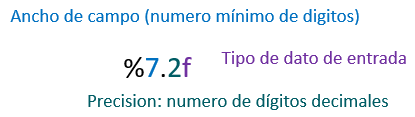

encabezado = sprintf('%5s %5s %5s %5s %5s\n', 'xi', 'ni', 'Ni', 'fi', 'Fi');
cuerpo= sprintf('%5d %5d %5d %5.2f %5.2f\n', tabla');%(sprintf da formato en orden de columna, por eso transponemos)
tabla=[encabezado cuerpo]

tabla =     '   xi    ni    Ni    fi    Fi
        45     5     5  0.05  0.05
        55    24    29  0.26  0.32
        65    35    64  0.38  0.70
        75    17    81  0.18  0.88
        85    10    91  0.11  0.99
        95     1    92  0.01  1.00
     '


Si quisieramos mostrar los límites de los intervalos de clases $\left.{\left\lbrack L\right.}_{i-1} ,L_i \right)$ en vez de las marcas de clase:

a=xi(2)-xi(1);%anchura de las clases
tabla=[xi'-a/2 xi'+a/2  ni' Ni' fi' Fi'];
encabezado = sprintf('%3s %3s  %5s %5s %5s %5s\n', '(Li-1,', 'Li]', 'ni', 'Ni', 'fi', 'Fi');
cuerpo= sprintf('%3.2f %3.2f %5d %5d %5.2f %5.2f\n', tabla');
tabla=[encabezado cuerpo]

tabla =     '[Li-1, Li)     ni    Ni    fi    Fi
     40.00 50.00     5     5  0.05  0.05
     50.00 60.00    24    29  0.26  0.32
     60.00 70.00    35    64  0.38  0.70
     70.00 80.00    17    81  0.18  0.88
     80.00 90.00    10    91  0.11  0.99
     90.00 100.00     1    92  0.01  1.00
     '


**Ejercicio propuesto 1: Tabla de frecuencias. **Obtén la tabla de frecuencias de la variable Altura. La tabla debe mostrar las frecuencias absolutas, relativas, absolutas acumuladas, y relativas acumuladas para cada clase o intervalo. Además incluye un encabezado. 

### `3.Estadísticos`

Prácticamente todos los estadísticos que hemos visto en clase están disponibles en Matlab (u Octave) como funciones que toman como argumento la muestra completa de datos en un vector. La mayoría de estas funciones se llaman simplemente como el nombre estadístico correspondiente en inglés: m*ean, median, mode, var, std, min, max, range, iqr, skewness, kurtosis*, ...

Si consultas la ayuda, verás que *var* y *std* calculan, en realidad, la cuasi-varianza y la cuasi-desviación típica. Consulta la ayuda de cada una de ellas también para conocer todas sus opciones. Muchas de ellas trabajan con matrices de datos y pueden aplicarse independientemente a filas o columnas. Ten en cuenta que las variables tendrán sus unidades correspondientes, a pesar de que Matlab trabaje únicamente con los valores numéricos.

Me = median(peso)

Me = 66.5700

Mo = mode(p1)  

Mo = 68

S2 = var(peso)   % cuasi-varianza 

S2 = 119.1975

S2n = var(peso, 1)  % varianza; ver: help var

S2n = 117.9019

RIC = iqr(peso) %rango intercuartílico 

RIC = 13.9150

R = range(peso) %rango o recorrido

R = 54.8600

Si no hay una función específica para un estadístico, siempre se puede definir una, ya sea en su propio fichero .m o asignando un manejador a una funcion anónima. Veamos un ejemplo de esto último para definir el **coeficiente de variación**:

CV = @(x) std(x)/mean(x)

CV = function_handle with value:
    @(x)std(x)/mean(x)


CV(peso)

ans = 0.1659

**Ejercicio propuesto 2: help mode **A pesar que el siguiente conjunto de datos es bimodal Matlab solo devuelve una de las modas, mira el help de la función mode para entender que está pasando.

datos=[ -2 0 3 3 3 4 5 5 5]

datos =     -2     0     3     3     3     4     5     5     5


mode(datos)

ans = 3

**Ejercicio propuesto 3: implementación función asimetría. **Implementa una función (anónima o en archivo .m) que calcule el coeficiente de asimetría. Comprueba el resultado obtenido para el vector x=[1 3 4 5 100] con la función de Matlab *skewness*.

Tip:  Puedes utilizar la función de Matlab std(x) que calcula la cuasi-desviación típica.

## 4. Gráficos

Matlab permite realizar gráficos descriptivos de muestras de datos de forma sencilla. Además, mediante el uso de distintas opciones y algunas operaciones podemos modificar el aspecto de estos gráficos a nuestro gusto.

#### Diagrama de sectores (pie charts) 

Este diagrama se puede realizar mediante la función `pie` (en inglés, este tipo de gráfico es un *pie chart*). Podemos utilizarlo en variables cualitativas o cuantitativas discretas con pocos valores diferentes.

Como argumentos de la función `pie` podemos pasar la frecuencia relativa de cada valor (especifica la proporción del área del círculo de cada sector) y las etiquetas de cada sector. También es posible pasar las frecuencias absolutas, como podrás comprobar consultando el help de la función.

 En el siguiente ejemplo utilizamos la variable `fuma`:

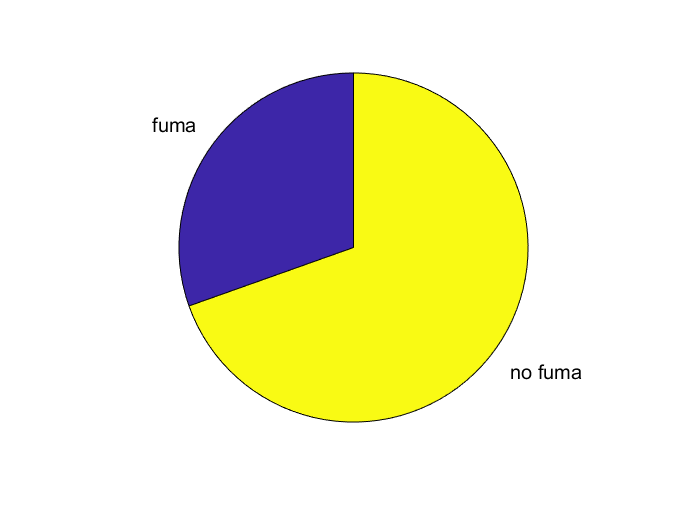

% pie(ni, labels) 
[xi, ~, ic] = unique(fuma);
ni = hist(ic, length(xi));
figure
pie(ni,xi)

#### Diagrama de barras 

Se puede obtener con la función ***bar*** (del inglés, *bar chart*). Está indicado para variables cualitativas o discretas con un número pequeño de posibles valores.  Por ejemplo, para la variable `fuma` que acabamos de ordenar, se puede hacer lo siguiente:

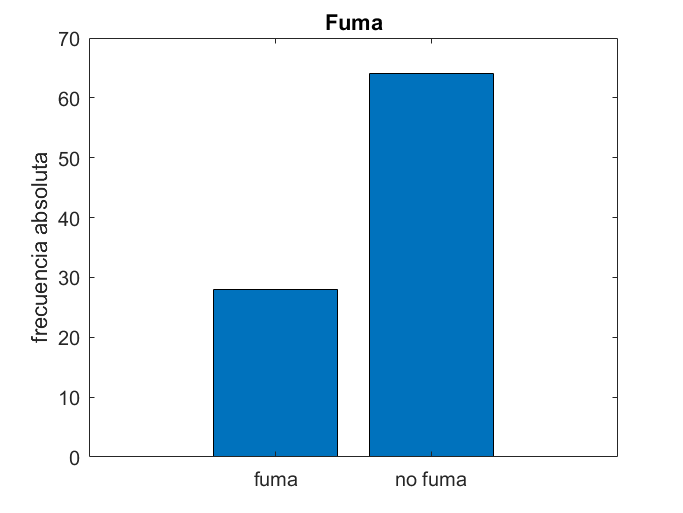

% bar(y), donde y especifica altura de las barras
figure
bar(ni)
title('Fuma');ylabel('frecuencia absoluta')
set(gca, 'XTickLabel', xi); 

El  comando *set(gca, 'XTickLabel', xi)* asigna, una vez realizado el gráfico, valores a cada marca del eje de abscisas. `gca` se refiere a *get current axis* y permite modificar de esta manera muchas de las opciones gráficas del ultimo gráfico dibujado. Para ver la lista de opciones que se pueden llegar a modificar, se puede introducir el comando `get(gca)`. Algunas de ellas como 'Xlabel' tiene comandos para cambiarlas directalmente como *xlabel()*, *xlim()* o* title()*.

A continuación se muestra el diagrama de barras de la variable cuantitativa discreta `p1`:

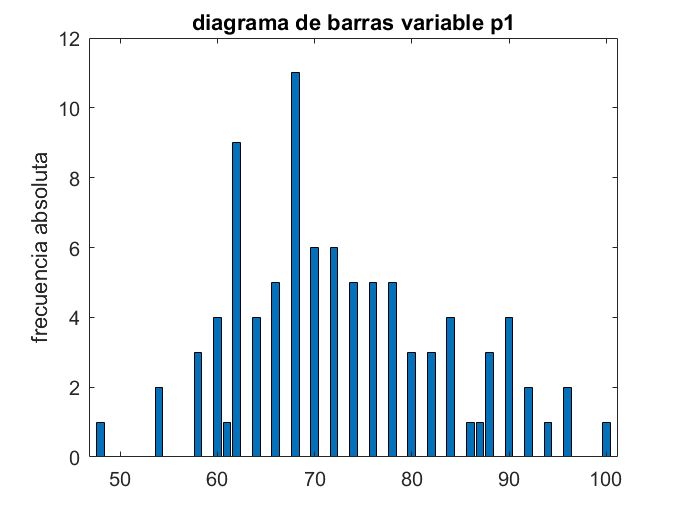

[xi, ~, ic] = unique(p1);
ni = hist(p1, xi);
figure
bar(xi,ni)
title('diagrama de barras variable p1');
ylabel('frecuencia absoluta')

En este caso, como la variable cuantitativa discreta toma un gran variedad de valores podíamos optar también por agruparlos.

#### Histogramas 

Para muestras de datos continuos (o discretos con muchos valores posibles), podemos representar un histograma. En realidad, ya vimos antes el comando ***hist*** (lo usamos para obtener las frecuencias absolutas). Cuando no se dan argumentos de salida a esta función, su comportamiento cambia y realiza un gráfico:

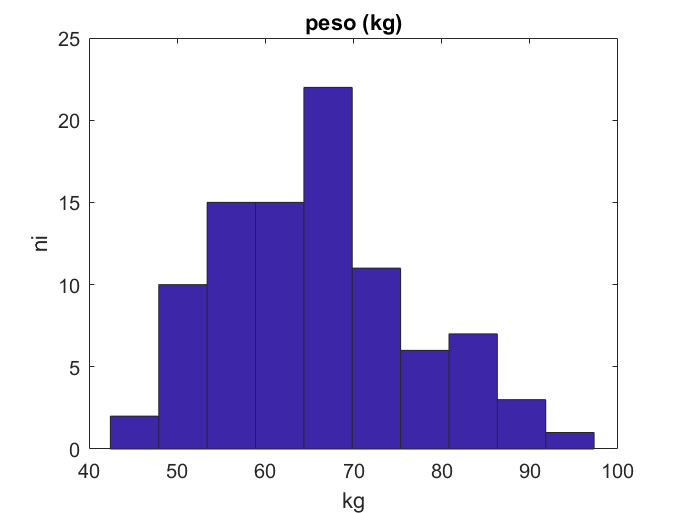

figure
hist(peso)
title('peso (kg)')
xlabel('kg'); ylabel('ni'); 

#### Diagramas de cajas

Se pueden hacer con la función ***boxplot***. Se trata de un gráfico adecuado para variables cuantitativas.

Obtén el diagrama de cajas de la variable cuantitativa peso. ¿Hay algún valor atípico en la muestra?

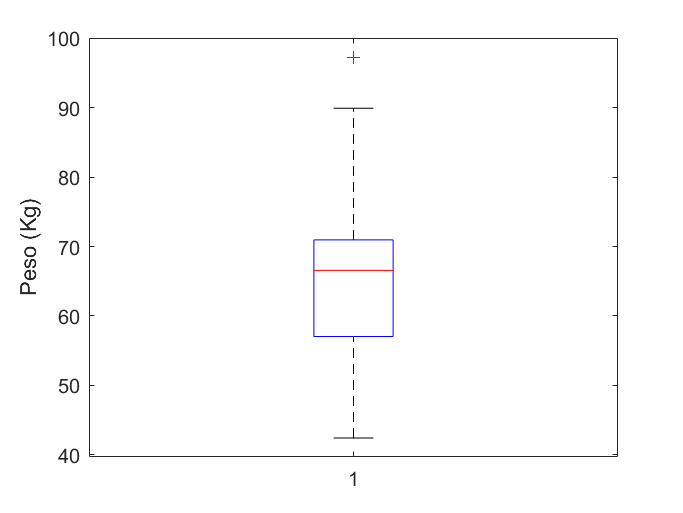

figure
boxplot(peso)
ylabel('Peso (Kg)');

### 5. Análisis factorizado. Filtrar mediante una variable cualitativa

En ocasiones interesa factorizar una variable de acuerdo a otra variable (factor), para estudiar por separado diferentes casos. Los datos factorizados pueden utilizarse después con tablas, estadísticos o gráficos.

Por ejemplo, podríamos querer analizar el peso de mujeres y hombres por separado. Una forma sencilla de seleccionar las mujeres de la muestra es la selección mediante **vectores lógicos**. Podemos crear uno a partir de la variable sexo:

M=strcmp(sexo,'mujer');
H=strcmp(sexo,'hombre');
sprintf('Número de mujeres: %d',sum(M))

ans = 'Número de mujeres: 35'

sprintf('Número de hombres: %d',sum(H))

ans = 'Número de hombres: 57'

**Análisis factorizado (estadísticos).** Podemos analizar preguntas tales como,¿Cuál es el peso medio de las mujeres?

sprintf('Peso medio de las mujeres: %.2f kg',mean(peso(M)))

ans = 'Peso medio de las mujeres: 56.11 kg'

 ¿y el peso medio de las de las mujeres fumadoras?¿ y de las mujeres no fumadoras?

F=strcmp(fuma,'fuma');
mean(peso(F&M))

ans = 57.5400

mean(peso(~F&M))

ans = 55.6811

A continuación se muestran los pesos medios factorizados segun la variable actividad.

baja=strcmp(act,'baja');
media=strcmp(act,'media');
alta=strcmp(act,'alta');
sprintf('Peso medio de la gente que realiza actividad baja: %.2f kg',mean(peso(baja)))

ans = 'Peso medio de la gente que realiza actividad baja: 67.84 kg'

sprintf('Peso medio de la gente que realiza actividad media: %.2f kg',mean(peso(media)))

ans = 'Peso medio de la gente que realiza actividad media: 65.15 kg'

sprintf('Peso medio de la gente que realiza actividad alta: %.2f kg',mean(peso(alta)))

ans = 'Peso medio de la gente que realiza actividad alta: 66.82 kg'

**Ejercicio propuesto 4.**¿Cuál es la altura media de las mujeres? ¿y de los hombres?

(comenta los resultado obtenidos aqui...)

**Análisis factorizado (gráficos).** 

La funcion ***boxplot*** de Matlab permite realizar **diagrama de cajas factorizados **rápidamente pasando un argumento que especifique los grupos.

boxplot(peso,sexo)
ylabel('Peso (Kg)');

Otro ejemplo seria factorizar la variable *peso* según el nivel de *actividad*.

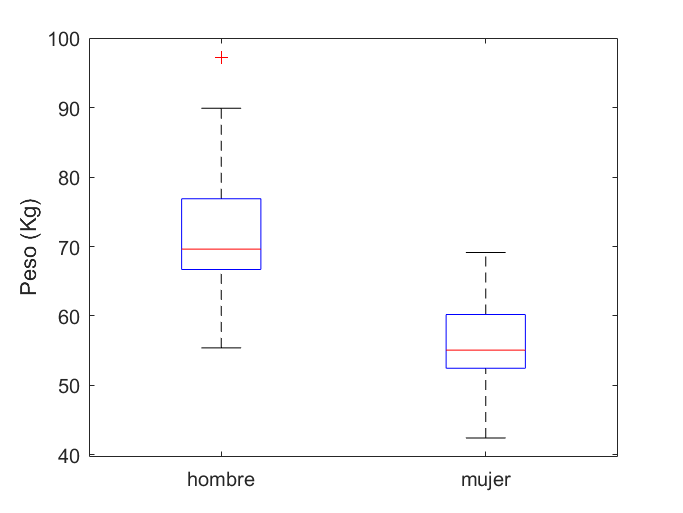

figure
boxplot(peso,act)

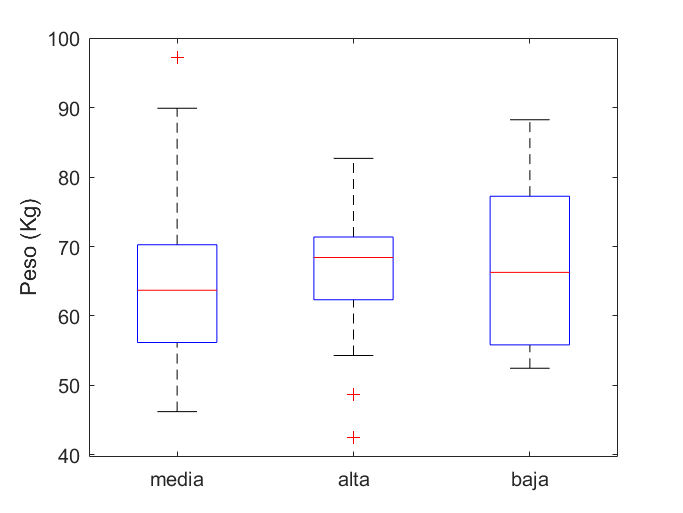

ylabel('Peso (Kg)');

**Múltiples gráficos en una figura. **Como hemos visto algunas funciones gráficas, como boxplot, permiten de forma nativa visualizar varios gráficos en una sola figura. En cualquier caso, siempre existe la opción de alinear dentro de una figura varios paneles con distintos gráficos en cada uno. Esto lo realiza la función `subplot`. 

`subplot(n,m,i)` permite escribir en el panel `i`-ésimo de una retícula de `nxm` paneles (n filas m columnas).

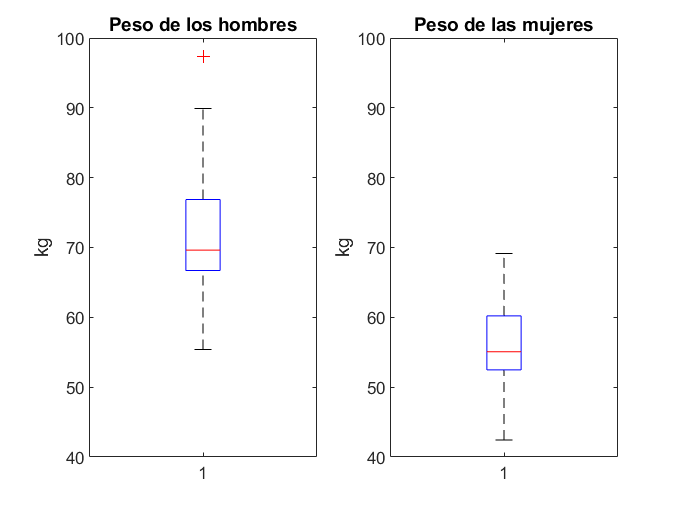

ylimites = [40,100];
figure
subplot(1,2,1)
  boxplot(peso(~M));
  ylim(ylimites);
  title('Peso de los hombres');ylabel('kg')
subplot(1,2,2)
  boxplot(peso(M));ylabel('kg')
  ylim(ylimites);
  title('Peso de las mujeres')

Nótese el uso de `ylim` para establecer ejes de ordenadas comunes a ambos paneles, de forma que los gráficos son directamente comparables.

Otra opción para combinar gráficos es usar la instrucción ***hold on***, que indica a Matlab que la siguiente instrucción gráfica la realice sin eliminar el gráfico anterior. Esto nos permite, por ejemplo, representar la muestra concreta encima de los diagramas de cajas a los que dan lugar:

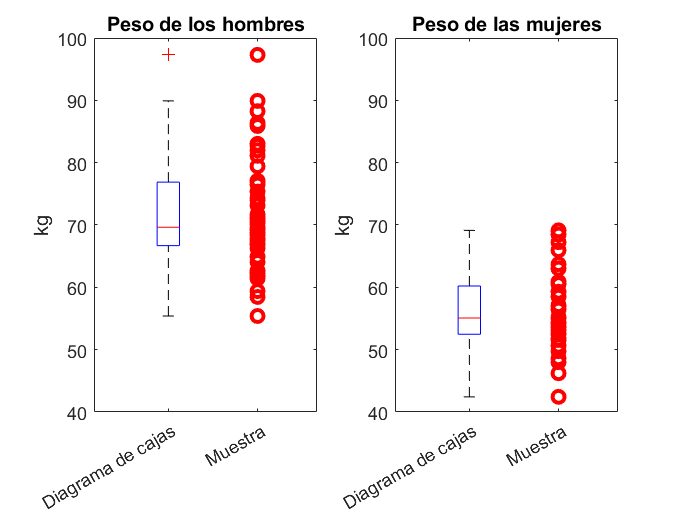

ylimites = [40,100];

figure;
subplot(1,2,1)
boxplot(peso(H));
ylim(ylimites);ylabel('kg')
title('Peso de los hombres')
xlim([0.5, 2])
hold on %la siguiente instruccion grafica se representara encima de la gráfica 
%representación de los datos concretos de peso
plot(ones(sum(H),1)*1.6,peso(H), 'or', 'LineWidth', 2);
set(gca, 'XTick', [1,1.6], 'XTickLabel', {'Diagrama de cajas', 'Muestra'}, 'FontSize', 9)

subplot(1,2,2)
boxplot(peso(M));
ylim(ylimites);ylabel('kg')
title('Peso de las mujeres')
xlim([0.5, 2])
hold on %la siguiente instruccion grafica se representara encima de la gráfica 
%representación de los datos concretos de peso
plot(ones(sum(M),1)*1.6,peso(M), 'or', 'LineWidth', 2);
set(gca, 'XTick', [1,1.6], 'XTickLabel', {'Diagrama de cajas', 'Muestra'}, 'FontSize', 9)

Nótese el uso de `xlim` para dejar espacio en el gráfico paa la representación de la muestra, que se ha añadido como una serie de círculos. Para representar los circulo usamos la funcion ***plot(x,y)*** de matlab a la que se le pasa un vector x con las coordenadas en el eje de abscisas y un vector y con las coordenadas de los puntos en el eje de ordenadas. La opcion de formato 'or' indica que se usen puntos rojos.

De la misma forma se podrían** mostrar varios histogramas**, o diagramas de sectores en la misma figura.

Obten el histograma de peso factorizado actividad

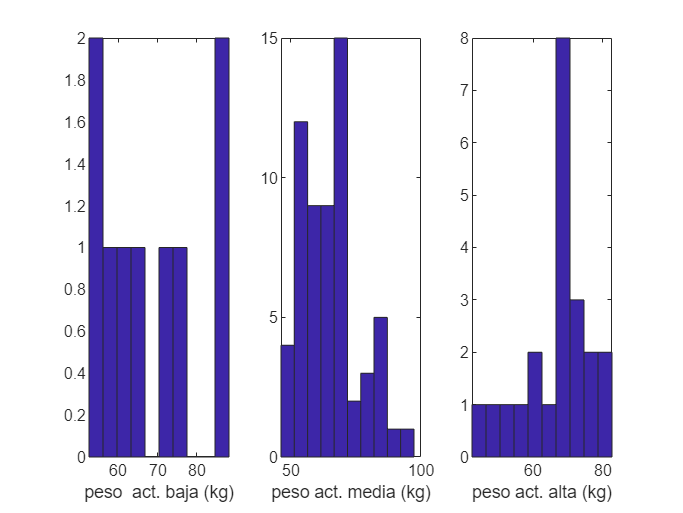

baja=strcmp(act,'baja');
media=strcmp(act,'media');
alta=strcmp(act,'alta');

figure;
subplot(1,3,1)
hist(peso(baja))
xlabel('peso  act. baja (kg)')

subplot(1,3,2)
hist(peso(media));
xlabel('peso act. media (kg)')

subplot(1,3,3)
hist(peso(alta));
xlabel('peso act. alta (kg)')

para que sean gráficos más comparables utilizamos las mismas marcas de clase y los mismos limites en el eje y.

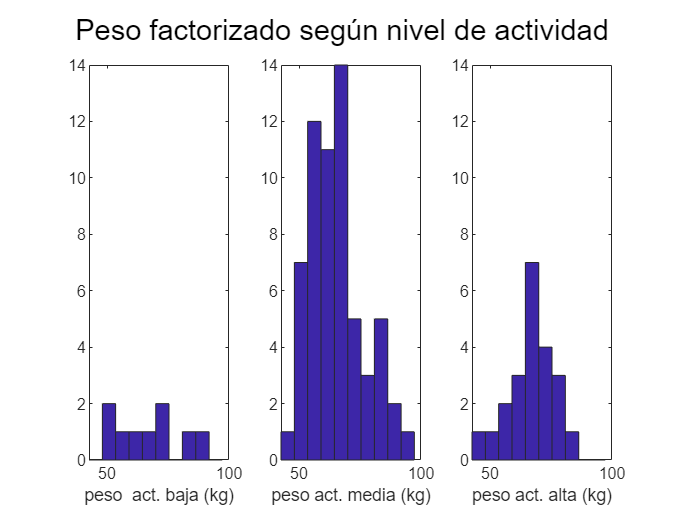

%obtenemos unos valores para las marcas de clase de los tres histogramas
[ni, xi] =hist(peso);

figure;
subplot(1,3,1)
hist(peso(baja),xi)
xlabel('peso  act. baja (kg)')
ylim([0 14])

subplot(1,3,2)
hist(peso(media),xi);
xlabel('peso act. media (kg)')
ylim([0 14])

subplot(1,3,3)
hist(peso(alta),xi);
xlabel('peso act. alta (kg)')
ylim([0 14])

sgtitle('Peso factorizado según nivel de actividad')%titulo de todos los subplots